# **Real-Time Audio Processing**

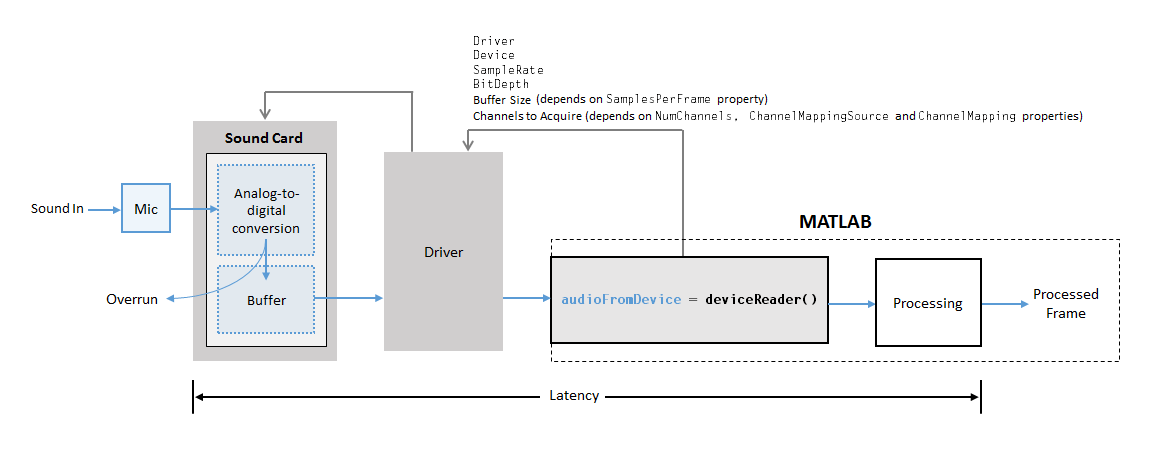

[https://www.mathworks.com/help/audio/gs/audio-io-buffering-latency-and-throughput.html](https://www.mathworks.com/help/audio/gs/audio-io-buffering-latency-and-throughput.html)

## ปัญหาหลักในการจัดการ real-time audio

- ข้อมูลเข้ามาอย่างต่อเนื่อง ทีละ frame

- ระดับสัญญาณไม่แน่นอน ขึ้นอยู่กับอุปกรณ์ทั้งฝั่งส่งและฝั่งรับและการปรับค่า

- ในแง่ของการแข่งขัน ต้องมีสัญญาณสั่งให้ระบบเริ่มต้นทำงาน

## **เตรียมการจำลอง real-time audio**

frameLength = 256;

fileReader = dsp.AudioFileReader('Examples\RunningAudio.wav', 'SamplesPerFrame', frameLength);
Fs = fileReader.SampleRate;


% Fs = 48000;
deviceReader = audioDeviceReader(Fs, frameLength);

deviceWriter = audioDeviceWriter('SampleRate', Fs);

## **สโคปสำหรับ real-time audio**

scope = timescope('SampleRate', Fs, 'TimeSpan', 2, 'BufferLength', Fs * 2, ...
                  'YLimits', [-1, 1], 'TimeSpanOverrunAction', 'scroll');

## การเตรียม audio buffer และ input normalization

bufferLength = round(5.0 * Fs);
audioBuffer = zeros(1, bufferLength);
bufferPosition = 1;
audioPositionSinceSync = 1;

## จำลอง real-time audio ด้วยไฟล์เสียง

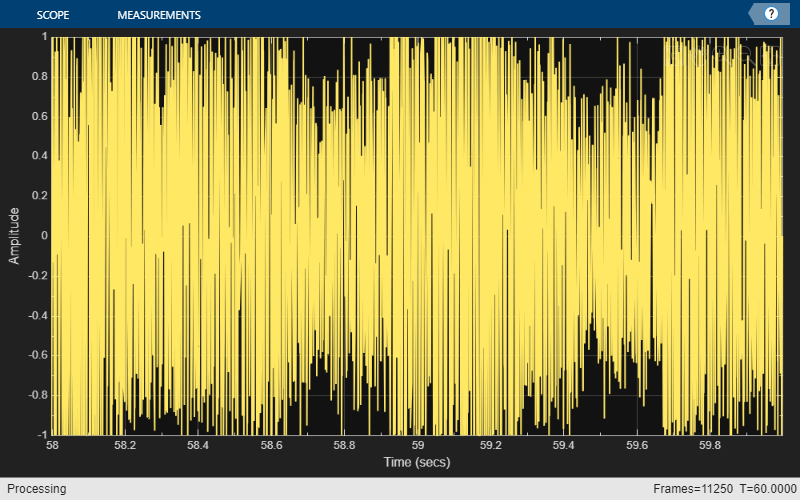

maxPeak = 0.0;
startThreshold = db2mag(-30);

% Wait for SYNC signal (sinusoid with amplitude larger than -30 dBFS)
while ~isDone(fileReader)
    signal = fileReader(); % read a new frame
    if max(signal) > startThreshold
        maxPeak = max(abs(signal));
        break;
    end
end

while ~isDone(fileReader)
    signal = fileReader(); % read a new frame

    % Adaptive normalization
    signalPeak = max(abs(signal));
    if signalPeak > maxPeak
        maxPeak = signalPeak;
    end
    signal = signal / maxPeak; % scale the signal towards 1.0

    % Handle audio buffer
    frameLength = length(signal);
    emptyLength = bufferLength - bufferPosition + 1;
    % Make space for the new frame 
    if emptyLength < frameLength
        moveOffset = frameLength - emptyLength;
        audioBuffer(1:bufferPosition-moveOffset-1) = audioBuffer(moveOffset+1:bufferPosition-1);
        bufferPosition = bufferPosition - moveOffset;
    end
    % Fill in the buffer with the new frame
    audioBuffer(bufferPosition:bufferPosition+frameLength-1) = signal;
    audioPositionSinceSync = audioPositionSinceSync + frameLength;

    % Process audio in the buffer (event detection)

    % Segment, classify, and report results

    % deviceWriter(signal);
    scope(signal);
end

## Real-time audio processing loop

processingTime = 5.0; % seconds
frameCount = processingTime * Fs / frameLength;
for i = 1:frameCount
    signal = deviceReader();

    % Perform normalization and buffering
    % Process audio buffer
    % Segment, classify, and report results

    deviceWriter(signal);
    scope(signal);
end

## Release resources

release(scope);
release(fileReader);
release(deviceReader);
release(deviceWriter);

## การระบุตำแหน่ง event

- ใช้การข้ามผ่าน threshold ของเส้นสัญญาณ

- ใช้การ crossing (ตัดกัน) ของเส้นสัญญาณสองเส้นหรือมากกว่า

## การใช้ moving RMS ในการหาตำแหน่ง event

[audioData, Fs] = audioread('Full-Length\Norm_2_52_pm_1.wav');

Error using audioread>readaudio (line 167)
The filename specified was not found in the MATLAB path.

Error in audioread (line 160)
    [y, Fs] = readaudio (filename, range, datatype);


shortWinLength = round(0.3 * Fs);
longWinLength = round(2.0 * Fs);

shortRMS = dsp.MovingRMS(shortWinLength);
longRMS = dsp.MovingRMS(longWinLength);

env1 = shortRMS(audioData);
env2 = longRMS(audioData);

จุดตัดในกรณีที่ไม่ชดเชยการเลื่อนของเวลา

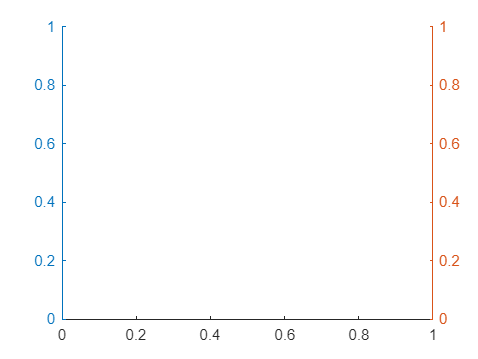

figure;
yyaxis left;

plot(audioData);

Unrecognized function or variable 'audioData'.

hold on;
yyaxis right;
plot(mag2db(env1), 'g-');
plot(mag2db(env2), 'm-');
hold off;

จุดตัดเมื่อชดเชยการเลื่อนของเวลา (ครึ่งของความยาว window)

shortOffset = round(shortWinLength/2);

Unrecognized function or variable 'shortWinLength'.

longOffset = round(longWinLength/2);

figure;
yyaxis left;
plot(audioData);
hold on;
yyaxis right;
plot(mag2db(env1(shortOffset:end)), 'g-');
plot(mag2db(env2(longOffset:end)), 'm-');
hold off;

## การใช้ DWT ในการหาตำแหน่ง event

ใช้ maximal overlap DWT (MODWT) ซึ่งจะไม่ลดสเกลเวลาในแต่ละระดับ

[audioData, Fs] = audioread('Full-Length\Norm_2_52_pm_1.wav');

Error using audioread>readaudio (line 167)
The filename specified was not found in the MATLAB path.

Error in audioread (line 160)
    [y, Fs] = readaudio (filename, range, datatype);

wt = modwt(audioData, 'db2', 'TimeAlign', true);
% wt = modwt(audioData, 'db2', 14, 'TimeAlign', true); % with level limit
size(wt)

เสียงต้นฉบับและ DWT ที่ระดับต่าง ๆ (แสดงระดับที่ 11-14)

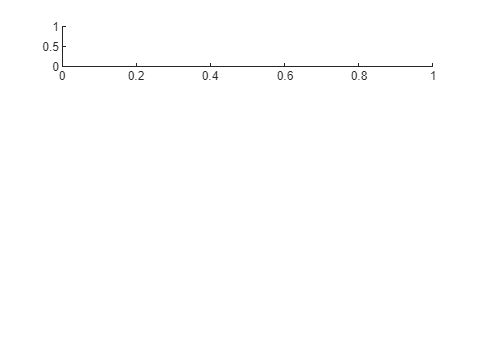

subplot(5, 1, 1);

plot(audioData);

Unrecognized function or variable 'audioData'.

axis tight;
for k = 11:14
    subplot(5, 1, k-9);
    plot(wt(k,:));
    axis tight;
    if k == 1
        title("MODWT Analysis");
    end
end

## การตัดช่วงเสียง (segmentation)

เมื่อระบุตำแหน่งได้แล้ว สามารถตัดช่วงเสียงได้โดยอาจมีการเผื่อด้านหน้าและด้านหลังตามความเหมาะสม เช่น เริ่มตัดที่ 0.1 วินาทีก่อนเหตุการณ์ โดยตัดให้มีความยาวทั้งสิ้น 0.8 วินาที เป็นต้น ความยาวอาจเลือกให้เหมาะสมเอง โดยไม่ยาวเกินไป (มีส่วนที่ไม่จำเป็นติดมาด้วยเยอะ) หรือสั้นเกินไป (อาจเก็บช่วงเหตุการณ์ที่สำคัญไม่ครบ)

ช่วงเสียงที่ตัดมาอาจผิดพลาดและไม่ใช่ช่วง stamp เสมอไป อาจต้องมีขั้นตอนการ classify เพิ่มเติมเพื่อคัดแยกช่วงเสียงที่ไม่ใช่ทิ้งไป